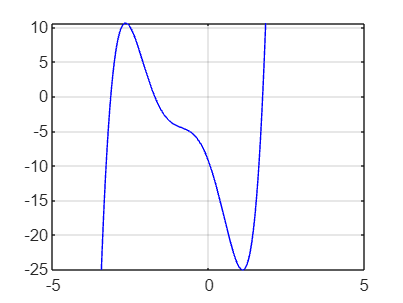

syms a b c d x

f(x) = (x^2+x+1)*(a*x^3+b*x^2+c*x+d);


f1 = subs(f, x, -pi);
f2 = subs(f, x, -sqrt(sym(3)));
f3 = subs(f, x, sqrt(sym(3)));
f4 = subs(f,x,0);

s = solve(f1 == 0, f2 == 0, f3 == 0,f4==-3*pi, a, b, c, d);
g(x)=subs(f,[a b c d],[s.a s.b s.c s.d]);

dg = diff(g, x);
c = solve(dg == 0, x,"Real",true);
m1 = subs(g, x, c(1));
m1y=g(m1);
m2 = subs(g, x, c(2));
m2y=g(m2);
m1=double(m1);
m2=double(m2);
fplot(g,'b');


ylim([m1 m2]);
yticks(-25:5:10);


grid on;